#### Name : Ghosh Kushanava Amitava

#### Roll No : 220123083

#### Course : MA 423

format long e

Iteration 1: Smallest singular value = 2.50930
Iteration 2: Smallest singular value = 2.42599
Iteration 3: Smallest singular value = 2.40495
Iteration 4: Smallest singular value = 2.45754
Iteration 5: Smallest singular value = 3.18734
Iteration 6: Smallest singular value = 2.31809
Iteration 7: Smallest singular value = 2.31983
Iteration 8: Smallest singular value = 2.12374
Iteration 9: Smallest singular value = 2.56168
Iteration 10: Smallest singular value = 2.86467


## Ref : 2nd Edition of Fundamentals of Matrix Computations

### PART - I

Q.1 

Ex 4.2.19

for k=1:10
    A = randn(40, 17);
    s = svd(A);
    fprintf('Iteration %d: Smallest singular value = %.5f\n', k, min(s));
end

Observation:

As, we can observe that smallest singular value is **almost never zero**, showing A is **full rank**

Ex 4.2.20

A = randn(8,4);

   1.3065e+00  -4.6871e-01  -1.2088e-01  -2.9546e-01   4.8640e-01  -1.0926e+00
   5.6281e-01  -9.3413e-01   2.7130e-01   2.1408e-01   1.3968e+00  -6.4039e-01
   8.1826e-01   3.8086e-01  -4.6303e-01  -1.3464e+00   4.5405e-01   5.2816e-01
  -8.9555e-01   3.5066e-01  -1.8855e-01  -7.8251e-01   4.0496e-01   1.2043e+00
   5.5172e-01  -7.2880e-01  -6.4764e-02  -3.6082e-01   9.6694e-01  -9.4621e-01
  -5.5989e-01  -1.2414e+00   1.0944e+00   2.3016e+00   9.3807e-01  -5.3144e-01
  -2.1040e-01  -1.5068e+00   3.1097e-01   3.1895e-01   1.7022e+00  -1.3618e+00
   1.4276e+00   5.4434e-01   4.5048e-01   3.0275e-01   9.9849e-01   2.2140e+00



A(:,5:6) = A(:, 1:2) + A(:, 3:4);
[Q, R] = qr(randn(6));
A = A*Q;

(a)

disp(A);

s =    4.5115e+00
   3.0909e+00
   2.9283e+00
   1.8072e+00
   4.4863e-16
   1.4550e-16


We **cannot tell** by looking at the printed matrix that it has rank 4.

(b)

format short e

r =      4


s = svd(A)

There are two tiny singular values which indicate numerical zeros, thereby confirming rank = 4.

(c)

r = rank(A)

R =      6


(d)

R = rank(A, 1e-16)

Ex 4.2.21

(a)

n = 90;
theta = 1.2;
A = gallery('kahan', n, theta, 0);

d = diag(A);

Largest diagonal entry = 1


disp(['Largest diagonal entry = ', num2str(max(d))]);

Smallest diagonal entry = 0.0019039


disp(['Smallest diagonal entry = ', num2str(min(d))]);

Observation:

- max(d) = 1

- min(d) > 0.001

(b)

format short e
sig = svd(A);

disp(sig(1:10));

   8.7893e+00
   1.4999e+00
   1.1754e+00
   1.0951e+00
   1.0205e+00
   9.5106e-01
   8.8632e-01
   8.2599e-01
   7.6977e-01
   7.1736e-01



disp(sig(end-9:end));

   4.5244e-03
   4.1946e-03
   3.8863e-03
   3.5980e-03
   3.3280e-03
   3.0743e-03
   2.8350e-03
   2.6071e-03
   2.3842e-03
   3.9606e-15




r = rank(A);
disp(['Numerical rank of A = ', num2str(r)]);

Numerical rank of A = 89


(c)

A_p = gallery('kahan', 90, 1.2, 25);

sig_p = svd(A_p);
disp(sig_p(end-9:end));

   4.5244e-03
   4.1946e-03
   3.8863e-03
   3.5980e-03
   3.3280e-03
   3.0743e-03
   2.8350e-03
   2.6071e-03
   2.3842e-03
   3.9606e-15



r_pert = rank(A_p);
disp(['Numerical rank of perturbed A = ', num2str(r_pert)]);

Numerical rank of perturbed A = 89



[Q, R, E] = qr(A_p);

dif = norm(eye(90) - E);
disp(['Difference from identity (should be small if no pivoting) = ', num2str(dif)]);

Difference from identity (should be small if no pivoting) = 0


disp(['Bottom-right entry of R = ', num2str(R(90,90))]);

Bottom-right entry of R = 0.0019039


Q.2

k =   5

Relative Error = 1.3116e-01

Compression Ratio = 0.0406

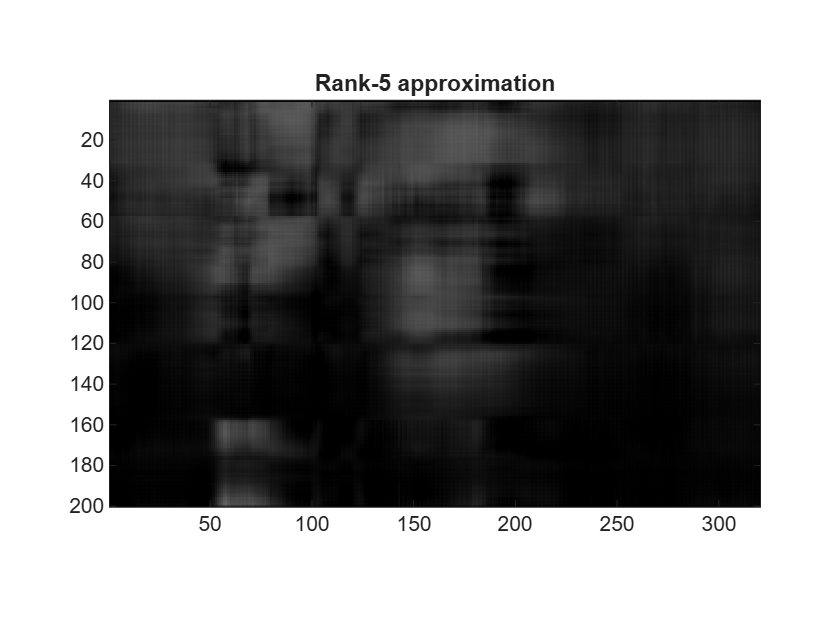

k =  10

Relative Error = 7.6621e-02

Compression Ratio = 0.0813

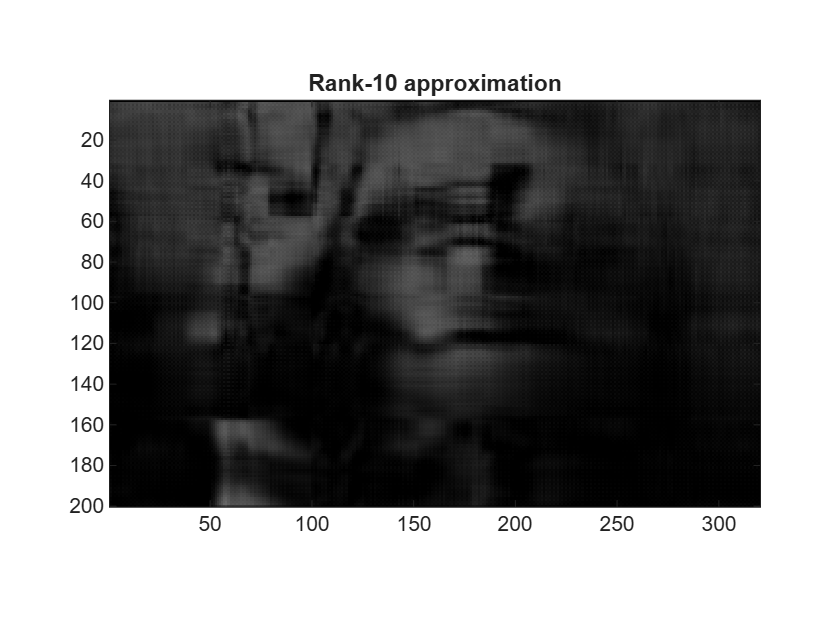

k =  20

Relative Error = 4.0313e-02

Compression Ratio = 0.1625

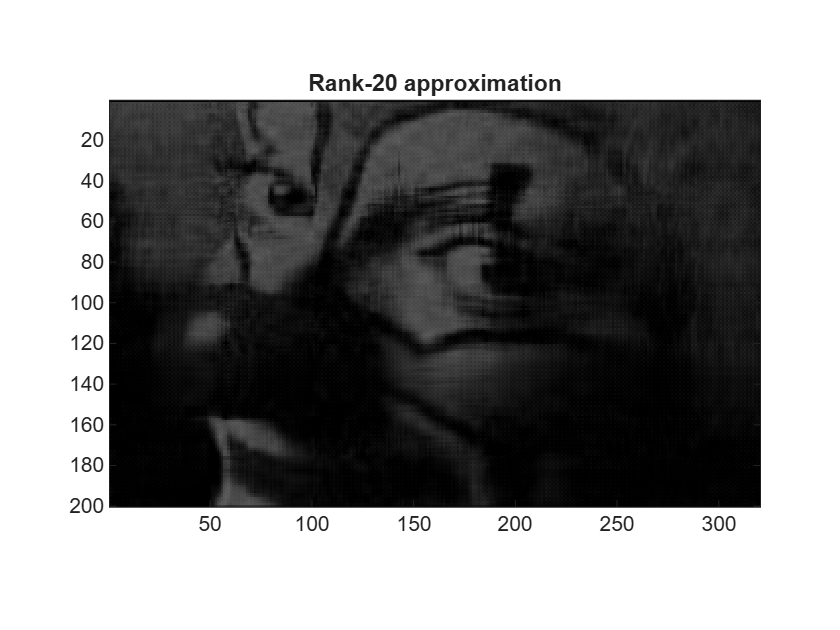

k =  50

Relative Error = 1.9189e-02

Compression Ratio = 0.4062

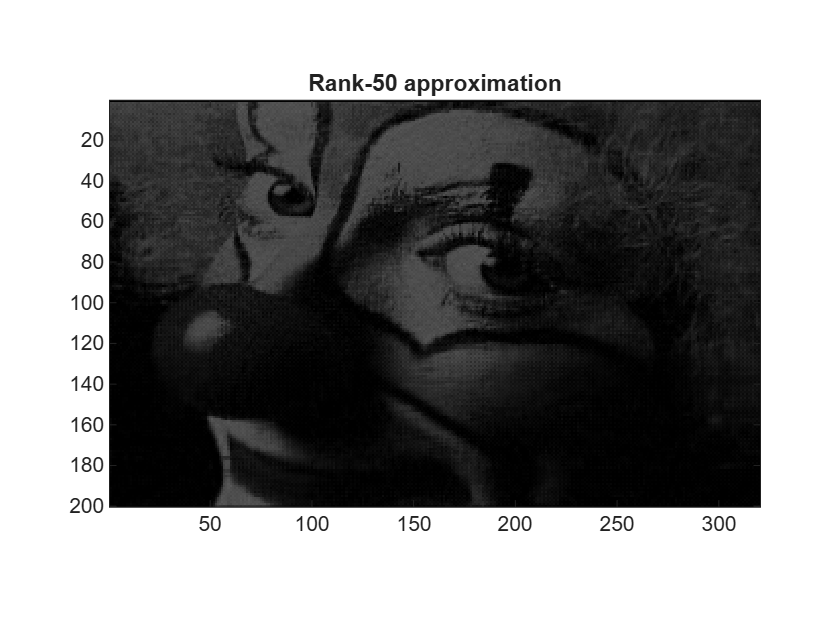

k = 100

Relative Error = 1.0434e-02

Compression Ratio = 0.8125

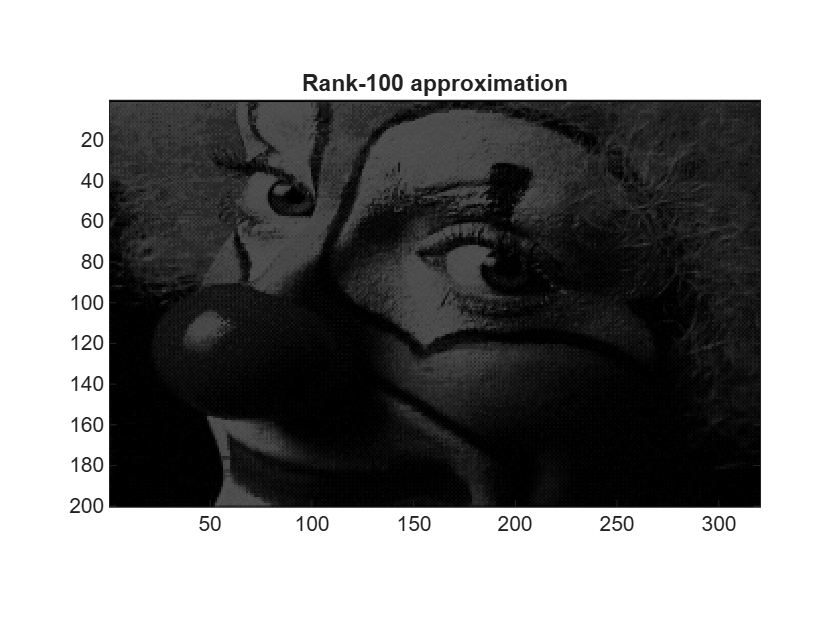

load clown.mat;
[U, S, V] = svd(X);
[m, n] = size(X);

K = [5, 10, 20, 50, 100];

for k = K
    Y = U(:,1:k) * S(1:k,1:k) * V(:,1:k)';
    rel_error = S(k+1,k+1) / S(1,1);
    comp_ratio = (k*(m+n)) / (m*n);
    fprintf('k = %3d', k);
    fprintf('Relative Error = %1.4e', rel_error);
    fprintf('Compression Ratio = %1.4f', comp_ratio);
    figure;
    image(Y);
    colormap('gray');
    axis image;
    title(['Rank-' num2str(k) ' approximation']);
end

### PART - II

Q.1 

n = [6, 7, 8];
m = [9, 10, 12];
for k = 1:3
    fprintf("Iteration %d", k);
    A = rand(m(k), n(k));
    [W, R] = polard1(A);
    fprintf("||WR - A|| = %e", norm(W*R - A));
    fprintf("||W'W - I|| = %e", norm(W'*W - eye(n(k))));
    fprintf("||R - R'|| = %e", norm(R - R'));
    fprintf("max(imag(eig(R))) = %e", max(imag(eig(R))));
    fprintf("min(eig(R)) = %e", min(eig(R)));
end

Iteration 1

||WR - A|| = 6.007892e-15

||W'W - I|| = 1.902931e-15

||R - R'|| = 2.918568e-16

max(imag(eig(R))) = 0.000000e+00

min(eig(R)) = 3.056792e-01

Iteration 2

||WR - A|| = 4.360702e-15

||W'W - I|| = 2.497292e-15

||R - R'|| = 3.661844e-16

max(imag(eig(R))) = 0.000000e+00

min(eig(R)) = 3.949994e-01

Iteration 3

||WR - A|| = 5.390650e-15

||W'W - I|| = 2.445076e-15

||R - R'|| = 3.049547e-16

max(imag(eig(R))) = 0.000000e+00

min(eig(R)) = 1.806320e-01

As, we can see that the norm(WR − A) (or norm(RW − A)), norm(W'W − I), (or norm(WW' − I)), norm(R − R'), max(imag(eig(R))) are of the order of **unit roundoff **and min(eig(R)) is **non-negative**.

If A is a square matrix of order n

A = rand(20, 20);
[W, R] = polard1(A);
fprintf("||WR - A|| = %e", norm(W*R - A));

||WR - A|| = 1.440468e-14

fprintf("||W'W - I|| = %e", norm(W'*W - eye(20)));

||W'W - I|| = 3.110109e-15

fprintf("||R - R'|| = %e", norm(R - R'));

||R - R'|| = 5.610310e-16

fprintf("max(imag(eig(R))) = %e", max(imag(eig(R))));

max(imag(eig(R))) = 0.000000e+00

fprintf("min(eig(R)) = %e", min(eig(R)));

min(eig(R)) = 6.289818e-02

As, norm(WR − A) (or norm(RW − A)), norm(W'W − I), (or norm(WW' − I)), norm(R − R'), max(imag(eig(R))) are of the order of **unit roundoff** and min(eig(R)) is **non-negative**. Moreover, the norm(R*R - A'A) is of the order of **unit roundoff**, which shows that R^2 = A*A.

Q.2

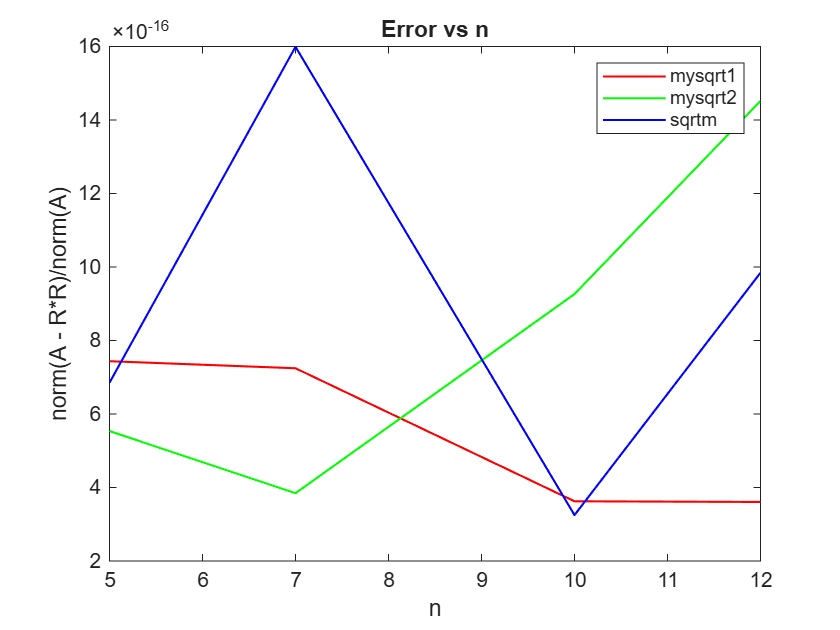

n = [5, 7, 10, 12];
X = [];
Y = [];
Z = [];
for i = n
    A = hilb(i);
    R1 = mysqrt1(A);
    R2 = mysqrt2(A);
    R3 = sqrtm(A);
    X(end + 1) = norm(A - R1 * R1)/norm(A);
    Y(end + 1) = norm(A - R2 * R2)/norm(A);
    Z(end + 1) = norm(A - R3 * R3)/norm(A);
end
plot(n, X, 'r', 'LineWidth', 1);
hold on;
plot(n, Y, 'g', 'LineWidth', 1);
hold on;
plot(n, Z, 'b', 'LineWidth', 1);
hold off;
xlabel('n');
ylabel('norm(A - R*R)/norm(A)');
title('Error vs n');
legend('mysqrt1', 'mysqrt2', 'sqrtm');

Observations:

- The relative error is almost always less for mysqrt1 function. Therefore, it is reliable and better.

- The relative error for mysqrt2 is almost always less than that of sqrtm.

Q.3 

n = [10, 20];
for i = 1:2
    A = rand(n(i), n(i));
    [W, R] = polard2(A);
    fprintf("Iteration %d", i);
    fprintf("||WR - A|| = %e", norm(W*R - A));
    fprintf("||W'W - I|| = %e", norm(W'*W - eye(n(i))));
    fprintf("||R - R'|| = %e", norm(R - R'));
    fprintf("max(imag(eig(R))) = %e", max(imag(eig(R))));
    fprintf("min(eig(R)) = %e", min(eig(R)));
    fprintf("||RR - A'A|| = %e", norm(R*R - A'*A));
end

Iteration 1

||WR - A|| = 4.332523e-16

||W'W - I|| = 9.836036e-13

||R - R'|| = 1.950704e-15

max(imag(eig(R))) = 0.000000e+00

min(eig(R)) = 1.736382e-02

||RR - A'A|| = 2.649478e-14

Iteration 2

||WR - A|| = 1.091817e-15

||W'W - I|| = 6.237275e-13

||R - R'|| = 3.093122e-15

max(imag(eig(R))) = 0.000000e+00

min(eig(R)) = 7.474358e-02

||RR - A'A|| = 3.976898e-14

(RW − A), norm(W'W − I), norm(R − R'), max(imag(eig(R))) are of the order of **unit roundoff **& min(eig(R)) is **non-negative**. Moreover, norm(R^2 - A'A) is of the order of **unit roundoff**, which shows that R^2 = A*A.

Comparing polard1 and polard2

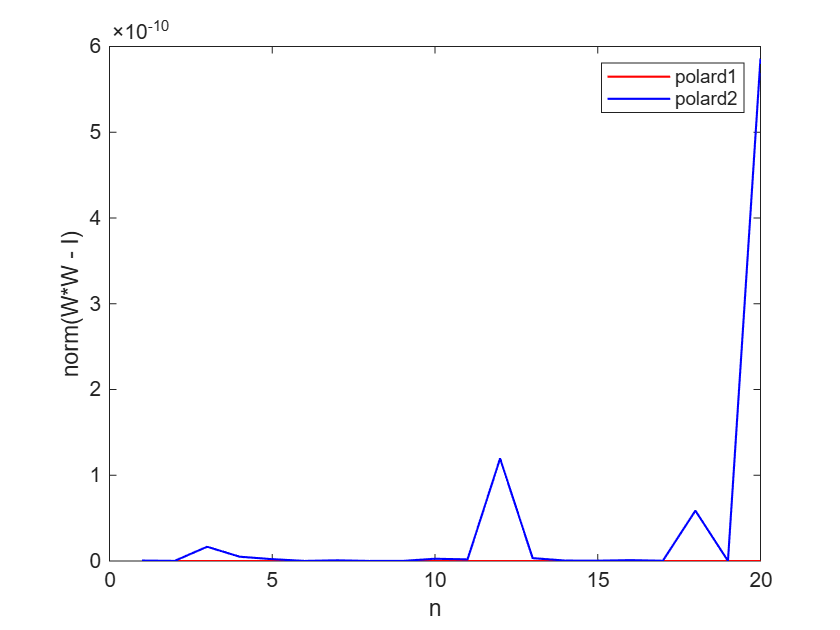

n = 20;
size = 30;
G = [];
H = [];
rng(9);
M = randn(size, size, n);
for j = 1 : n
   mat = M(:, :, j);
   [U, S, V] = svd(mat);
   S = sort(diag(S), 'descend');
   S = (S / S(end)) * (10^(-j + 6));
   S = diag(S);
   A = U * S * V';
   [W, R] = polard1(A);
   [X, T] = polard2(A);
   G(end + 1) = norm(W' * W - eye(size));
   H(end + 1) = norm(X' * X - eye(size));
end
x_range = (1:n);
plot(x_range, G, 'r', 'LineWidth', 1);
hold on;
plot(x_range, H, 'b', 'LineWidth', 1);
hold off;
xlabel('n');
ylabel('norm(W*W - I)');
legend('polard1', 'polard2');

Observation:

- polard1 is better and more reliable than polard2. 

- The relative difference in both the methods is very high as compared to the norm difference parameter.

Q.4

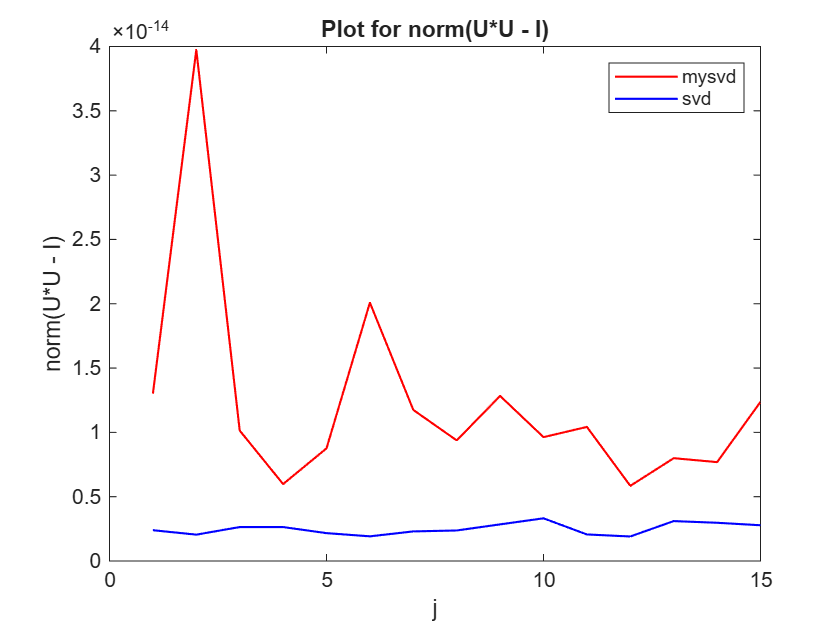

[n, size] = deal(15, 20);
[q, w, e, r] = deal([]);
rng(42);
M = randn(size, size, n);
for j = 1 : n
   y = M(:, :, j);
   [U, S, V] = svd(y);
   S = sort(diag(S), 'descend');
   S = (S / S(end)) * (10^(-j + 6));
   S = diag(S);
   A = U * S * V';
   [U1, S1, V1] = mysvd(A);
   [U2, S2, V2] = svd(A);
   q(end + 1) = norm(U1' * U1 - eye(size));
   w(end + 1) = norm(U2' * U2 - eye(size));
   e(end + 1) = norm(V1' * V1 - eye(size));
   r(end + 1) = norm(V2' * V2 - eye(size));
end
x = (1:n);
figure();
plot(x, q, 'r', 'LineWidth', 1);
hold on;
plot(x, w, 'b', 'LineWidth', 1);
hold off;
xlabel('j');
ylabel('norm(U*U - I)');
title('Plot for norm(U*U - I)');
legend('mysvd', 'svd');

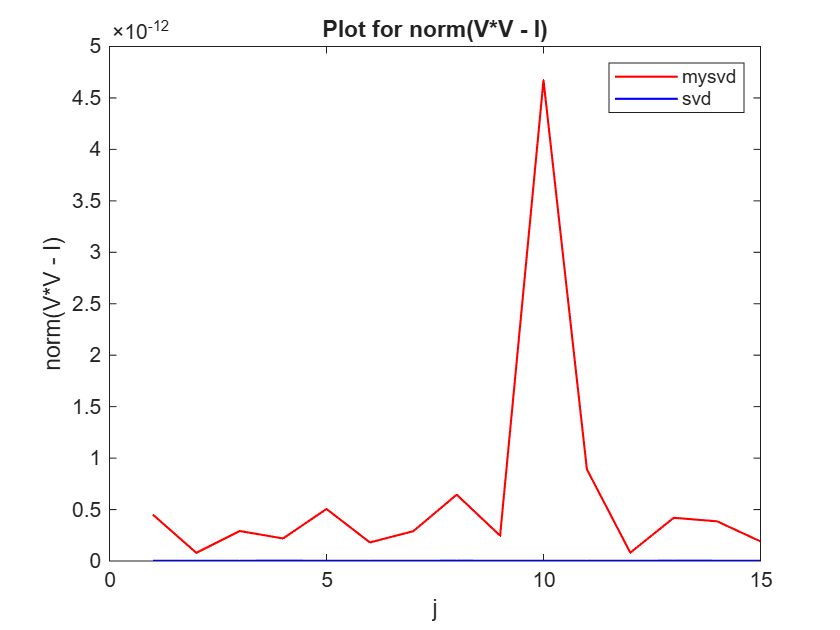

figure();
plot(x, e, 'r', 'LineWidth', 1);
hold on;
plot(x, r, 'b', 'LineWidth', 1);
hold off;
xlabel('j');
ylabel('norm(V*V - I)');
title('Plot for norm(V*V - I)');
legend('mysvd', 'svd');

Observation:

- From the plots that the inbuilt svd function is better than mysvd.

- U and V depart more from orthogonality using mysvd than using inbuilt svd function.

### Functions

function [W, R] = polard1(A)
    [m, n] = size(A);
    [U, S, V] = svd(A, 'econ');

    if m >= n
        R = V * S * V';       
        W = U * V';          
    else
        R = U * S * U';      
        W = U * V';         
    end
end

function R = mysqrt1(A)
    [X, D] = eig(A);
    R = (X * sqrt(D))/X;
end

function R = mysqrt2(A)
    R = chol(A);
    [U, S, V] = svd(R);
    R = V * S * V'; 
end

function [W, R] = polard2(A)
    R = mysqrt1(A'*A);
    W = A/R;
end

function [U, S, V] = mysvd(A)
    [W, R] = polard2(A);
    [V, S] = eig(R);
    [D, idx] = sort(diag(S), 'descend');
    S = diag(D);
    V = V(:, idx);
    U = V;
    V = W'*V;
end